# Повышение частоты дискретизации в целое число раз

#### Формирование исходного гармонического сигнала с частотой дискретизации fs = 8000 Гц и основной частотой повторения 1000 Гц:

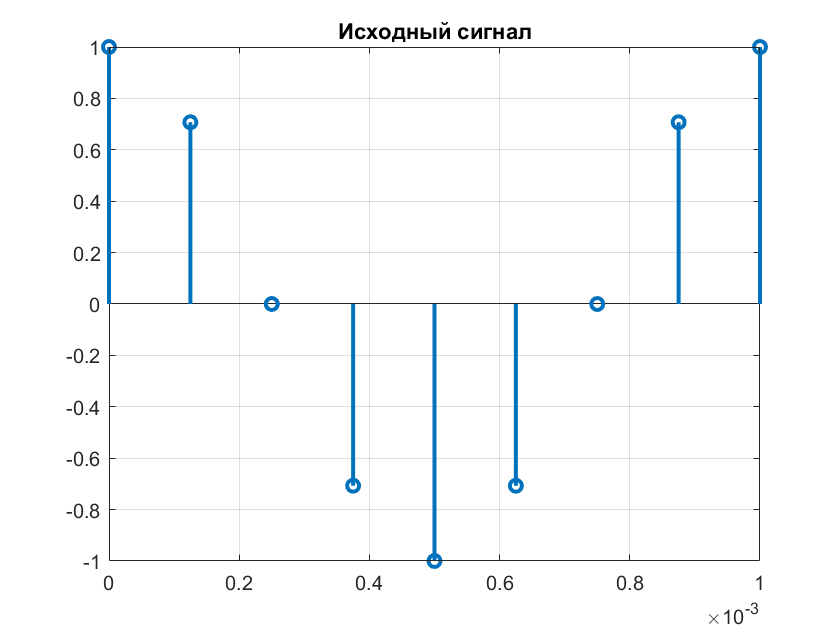

fs = 8000;
t1 = 0:1/fs:1;
f0 = 1000;
x = cos(2*pi*f0*t1);
stem(t1,x,'LineWidth',2);
title('Исходный сигнал');
xlim([0 1e-3]);
grid on;

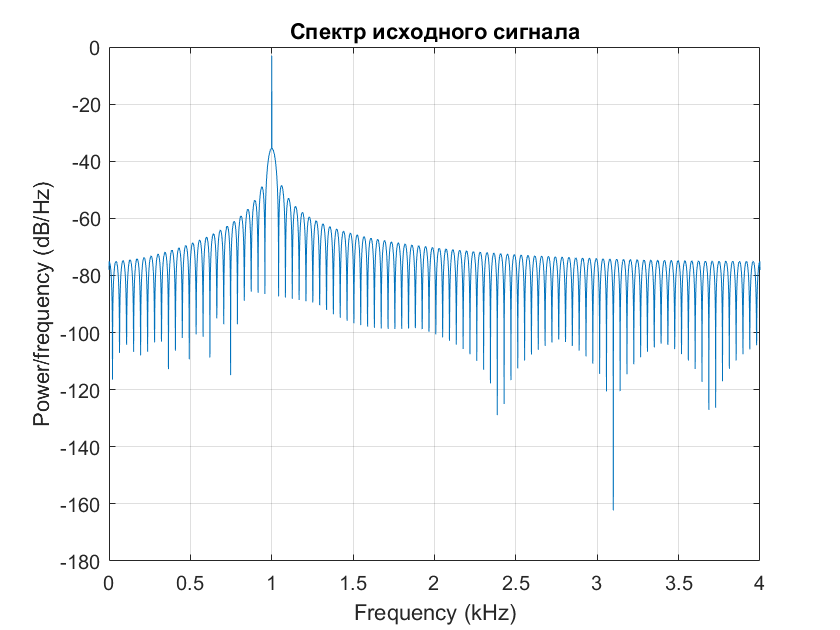

sound(x,fs);
periodogram(x,[],[],fs);
title('Спектр исходного сигнала');

#### Повышение частоты дискретизации методом upsampling:

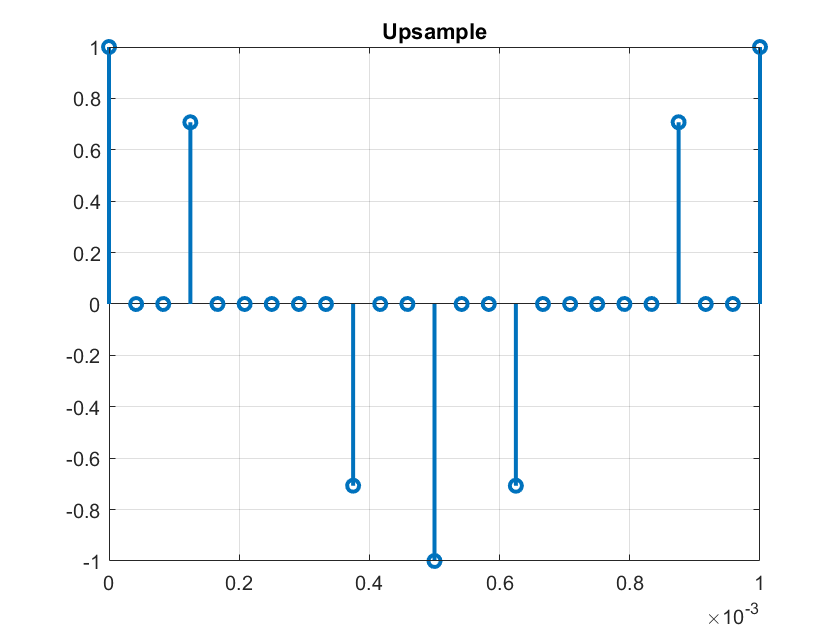

up = 3;
y_up = upsample(x,up);
y_up = y_up(1:end-(up-1));
t2 = 0:1/(fs*up):1;
stem(t2,y_up,'LineWidth',2);
title('Upsample');
xlim([0 1e-3]);
grid on;

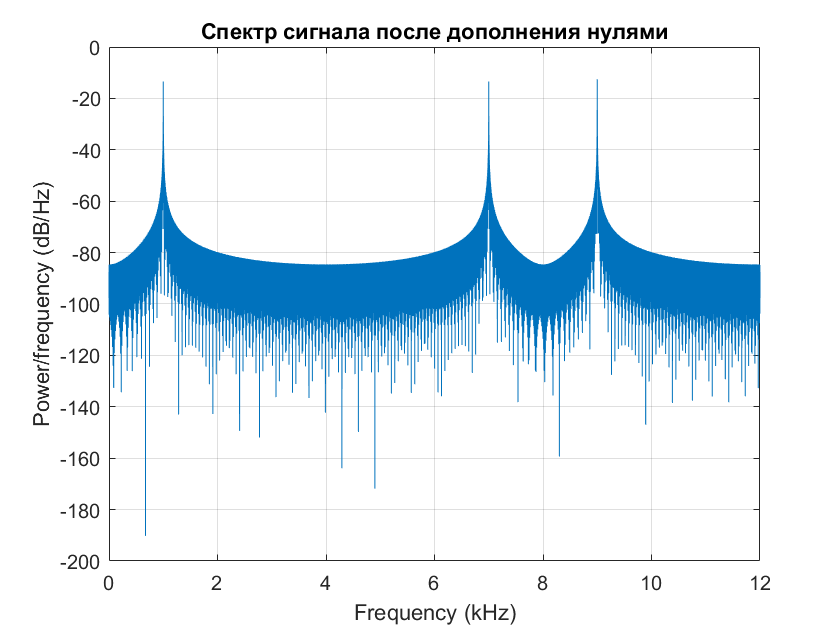

sound(y_up,fs*up)
periodogram(y_up,[],[],fs*up);
title('Спектр сигнала после дополнения нулями');

#### Повышение частоты дискретизации методом repeat:

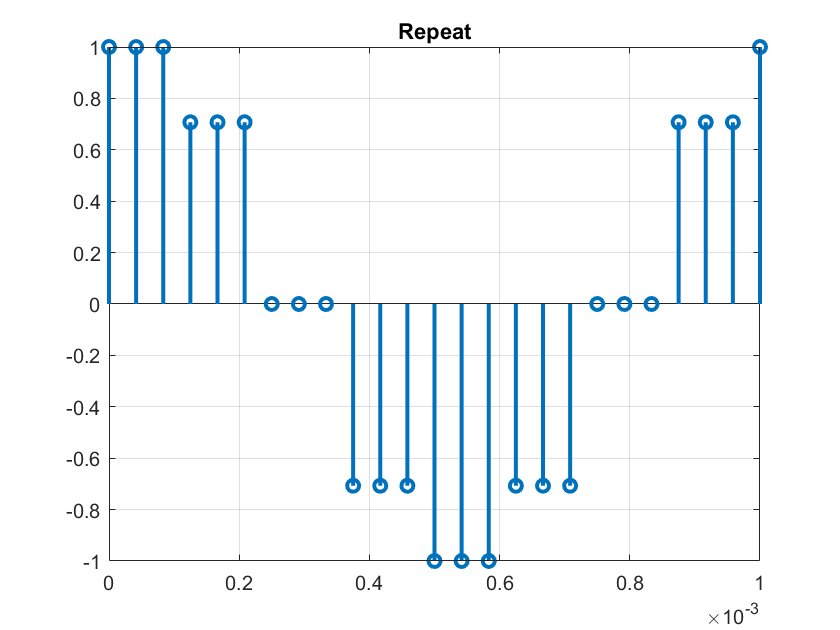

y_rep = repelem(x,up);
y_rep = y_rep(1:end-(up-1));
stem(t2,y_rep,'LineWidth',2);
title('Repeat');
xlim([0 1e-3]);
grid on;

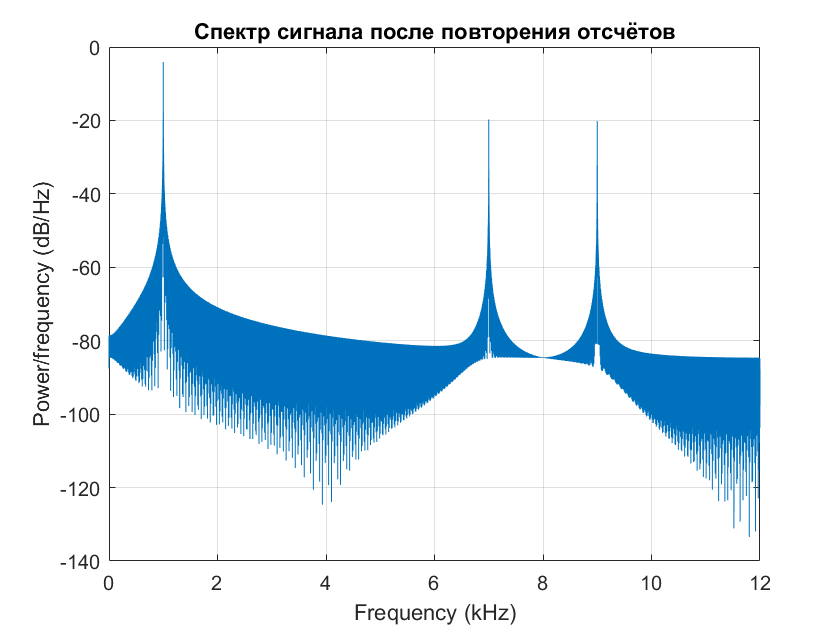

sound(y_rep,fs*up);
periodogram(y_rep,[],[],fs*up);
title('Спектр сигнала после повторения отсчётов');

#### Повышение частоты дискретизации методом interpolation:

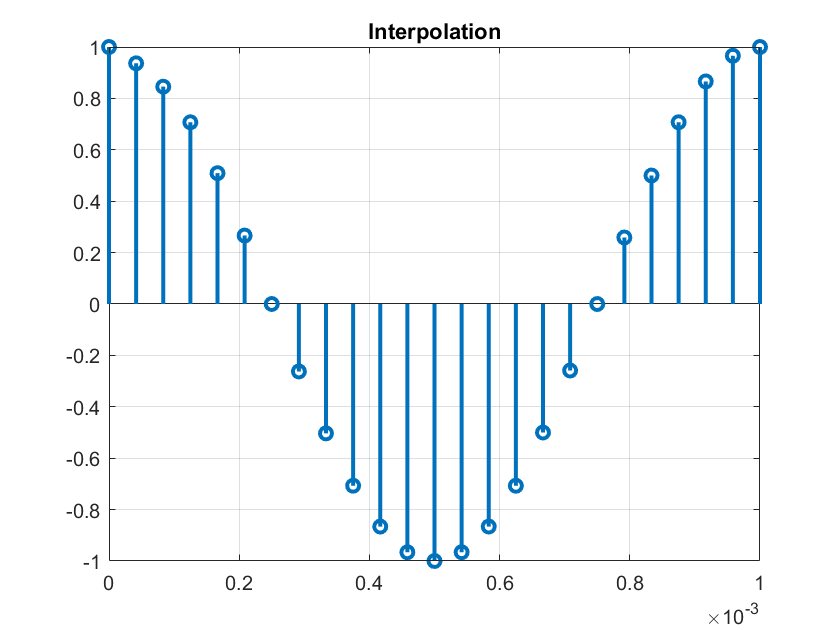

y_interp = interp(x,up); 
y_interp = y_interp(1:end-(up-1));
stem(t2,y_interp,'LineWidth',2);
title('Interpolation');
xlim([0 1e-3]);
ylim([-1 1]);
grid on;

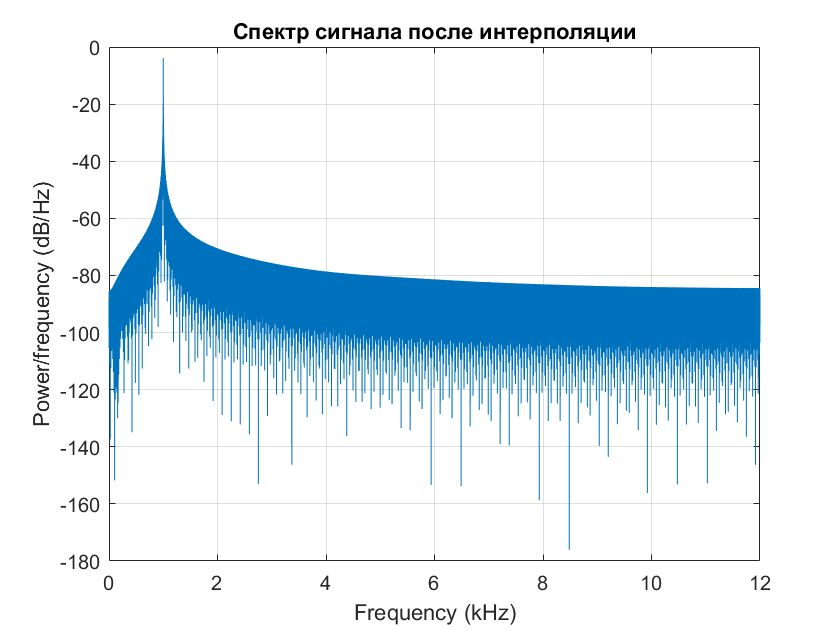

sound(y_interp,fs*up);
periodogram(y_interp,[],[],fs*up);
title('Спектр сигнала после интерполяции');